## T3_GA_P02. Análisis en estado estacionario de un sistema de reactores (2)

Uno de los principios más importantes en la ingeniería química es la conservación de la masa. En términos cuantitativos, el principio se expresa como un balance de masa que tiene en cuenta todas las fuentes y sumideros de un material que entra y sale de un volumen. En un periodo finito, esto se expresa como:

**Acumulación = Entradas **$-$** Salidas **  (1)

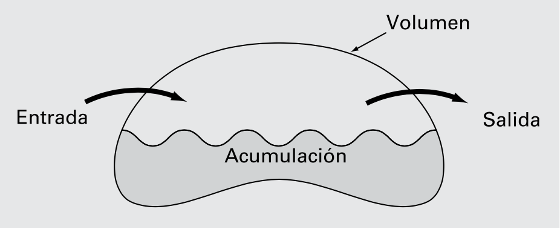

El balance de masa representa un ejercicio de registro para la sustancia en particular que se modela. Para el periodo en que se calcula, si las entradas son mayores que las salidas, la masa de la sustancia dentro del volumen aumenta. Si las salidas son mayores que las entradas, la masa disminuye. Si las entradas son iguales a las salidas, la acumulación es cero y la masa permanece constante. Para esta condición estable, o en estado estacionario, la ecuación anterior se expresa como

**Entradas = Salidas  **      (2) 

Emplearemos la conservación de la masa para determinar las concentraciones en estado estacionario de un sistema de reactores conectados.

Se puede usar el balance de masa para resolver problemas de ingeniería al expresar las entradas y salidas en términos de variables y parámetros medibles. Por ejemplo, si se realiza un balance de masa para una sustancia conservativa (es decir, aquella que no aumente ni disminuya debido a transformaciones químicas) en un reactor, podríamos cuantificar la velocidad con la cual el flujo de la masa entra al reactor a través de dos tuberías de entrada y sale de éste a través de una tubería de salida. 

 Esto se hace mediante el producto de la velocidad del fluido o caudal  $Q$ (en metros cúbicos por minuto) por la concentración $c$ (en miligramos por metro cúbico) en cada tubería. 

 Por ejemplo, en la tubería 1 de la figura, $Q_1 =2\;\frac{m^3 }{\min }$  y $c_1 =25\;\frac{\textrm{mg}}{m^3 }$ ;  por lo tanto, la velocidad con la cual la masa fluye hacia el reactor a través de la tubería 1 es $Q_1 \cdot c_1 =50\;\;\frac{\textrm{mg}}{\min }$ . Así, 50 mg de sustancias químicas fluyen cada minuto hacia el interior del reactor a través de esta tubería. 

 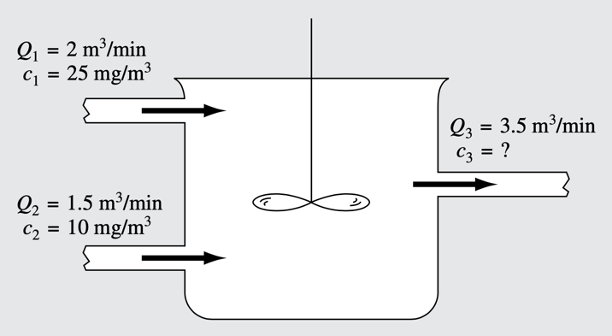

De forma similar, para la tubería 2 la velocidad de masa que entra se calcula como:$Q_2 c_2 =1\ldotp 5\;\left(\frac{m^3 }{,\textrm{in}}\right)\cdot 10\left(\frac{\textrm{mg}}{m^3 }\right)=15\;\frac{\textrm{mg}}{\min }$

Observa que la concentración a la salida del reactor a través de la tubería 3 no se especifica. Esto es así porque ya se tiene información suficiente para calcularla en base en la conservación de la masa. Como el reactor se halla en estado estacionario se aplica la ecuación (2) y las entradas deberán estar en equilibrio con las salidas:

 
$$Q_1 c_1 +Q_2 c_2 =Q_3 c_3$$


Sustituyendo los valores dados en esta ecuación se obtiene:$50+15=3\ldotp 5\;c_3 \to c_3 =\frac{65}{3\ldotp 5}=18\ldotp 6\;\frac{\textrm{mg}}{m^3 }$

De esta forma, hemos determinado la concentración en la tercera tubería. Sin embargo, del cálculo se obtiene algo más. Como el reactor está bien mezclado (representado por el agitador en la figura), la concentración será uniforme, u homogénea, en todo el tanque. Por lo que la concentración en la tubería 3 deberá ser idéntica a la concentración en todo el reactor. En consecuencia, el balance de masa nos ha permitido calcular tanto la concentración en el reactor como en el tubo de salida. Esta información es de gran utilidad para los ingenieros químicos y petroleros, quienes tienen que diseñar reactores que tengan mezclas de una concentración específica.

Debido a que se utilizó álgebra simple para determinar la concentración de un solo reactor, podría no ser obvio lo que tiene que hacer una computadora en el cálculo de un balance de masa. En la siguiente figura se muestra un problema donde las computadoras no solamente son útiles, sino que son de una enorme necesidad práctica. Debido a que hay cinco reactores interconectados o acoplados, se necesitan cinco ecuaciones de equlibrio de masa para caracterizar el sistema. 

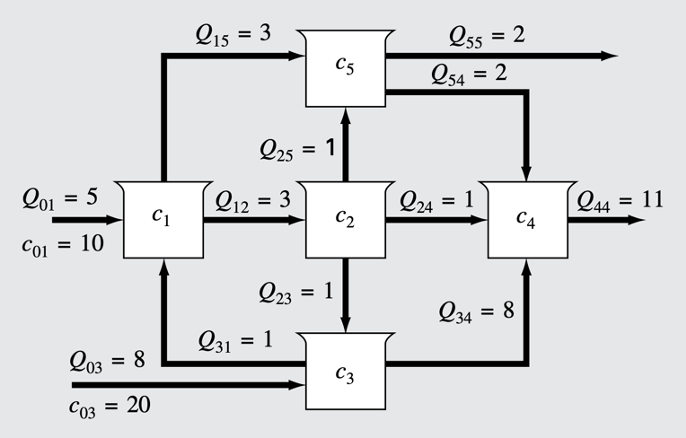

En el reactor 1, la velocidad de la masa que entra es: $5\cdot 10+Q_{31} \cdot c_3$ y la velocidad de la masa que sale es: $Q_{12} \cdot c_1 +Q_{25} \cdot c_1$

Como el sistema se encuentra en estado estacionario, los flujos de entrada y de salida deben ser iguales:


$$5\cdot 10+Q_{31} \cdot c_3 =Q_{12} \cdot c_1 +Q_{25} \cdot c_1$$


o, sustituyendo los valores de la figura: $6c_1 -c_3 =50$

Ecuaciones similares se obtienen para los otros reactores:


$$\begin{array}{l}
-3c_1 +3c_2 =0\\
-c_2 +9c_3 =160\\
-c_2 -8c_3 +11c_4 -2c_5 =0\\
-3c_1 -c_2 +4c_5 =0
\end{array}$$


Se puede utilizar un método numérico para resolver estas cinco ecuaciones con las cinco incógnitas que son las concentraciones.

 
$$A\cdot \mathit{\mathbf{C}}=\mathit{\mathbf{b}}$$


donde:

 
$$A=\left\lbrack \begin{array}{ccccc}
6 & 0 & -1 & 0 & 0\\
-3 & 3 & 0 & 0 & 0\\
0 & -1 & 9 & 0 & 0\\
0 & -1 & -8 & 11 & -2\\
-3 & -1 & 0 & 0 & 4
\end{array}\right\rbrack \;\;\;\;\;\;\;\;\;C=\left\lbrack \begin{array}{c}
c_1 \\
c_2 \\
c_3 \\
c_4 \\
c_5 
\end{array}\right\rbrack \;\;\;\;\;\;\;b=\left\lbrack \begin{array}{c}
50\\
0\\
160\\
0\\
0
\end{array}\right\rbrack$$


obteniendo la solución:

 
$$C=\left\lbrack \begin{array}{c}
11\ldotp 51\\
11\ldotp 51\\
19\ldotp 06\\
16\ldotp 99\\
11\ldotp 51
\end{array}\right\rbrack$$


La inversa de A es:

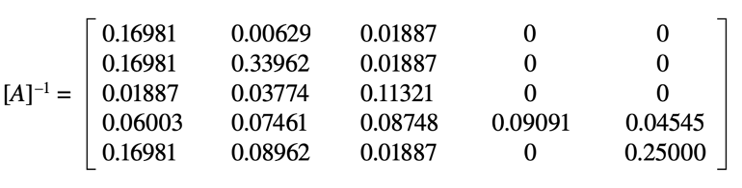 

Cada uno de los elementos  $a_{\textrm{ij}}$ significa el cambio en la concentración del reactor  $i$ debido a un cambio unitario en la carga del reactor $j$ . De esta forma, los ceros en la columna 4 indican que una carga en el reactor 4 no influirá sobre los reactores 1, 2, 3 y 5. Esto es consistente con la configuración del sistema, la cual indica que el flujo de salida del reactor 4 no alimenta ningún otro reactor. En cambio, las cargas en cualquiera de los tres primeros reactores afectarán al sistema completo, como se indica por la ausencia de ceros en las primeras tres columnas. Tal información es de gran utilidad para los ingenieros que diseñan y manejan sistemas como éste.

#### **Problema**

La figura ilustra un proceso de intercambio químico que consiste en una serie de reactores en los que un gas que fluye de izquierda a derecha pasa por un líquido que fluye de derecha a izquierda. La transferencia de un producto químico del gas al líquido ocurre a una tasa proporcional a la diferencia entre las concentraciones del gas y el líquido en cada reactor. 

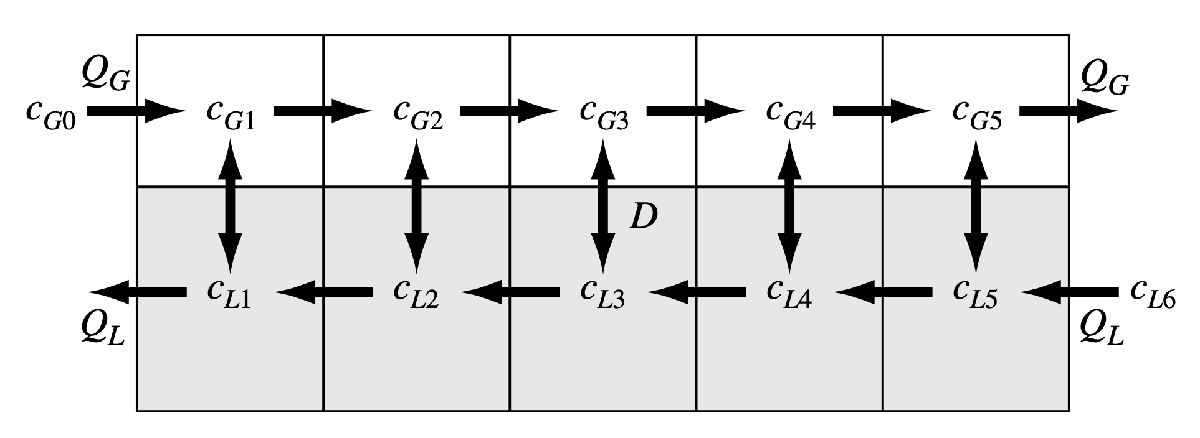

En estado estacionario (estable), el balance de masa para el primer reactor se puede escribir para el gas, así:


$$Q_G \cdot c_{\textrm{G0}} -Q_G \cdot c_{\textrm{G1}} +D\left(c_{\textrm{L1}} -c_{\textrm{G1}} \right)=0$$
					

y para el líquido, 


$$Q_L \cdot c_{\textrm{L2}} -Q_L \cdot c_{\textrm{L1}} +D\left(c_{\textrm{G1}} -c_{\textrm{L1}} \right)=0$$


donde $Q_G$ y $Q_L$ son las tasas de flujo del gas (caudal en $\left(\frac{m^3 }{s}\right)$) y el líquido, respectivamente, y *D *= tasa de intercambio gas-líquido. Es posible escribir otros balances similares para los demás reactores. 

Se desea conocer las concentraciones $\left(c_{\textrm{G1}} ,c_{\textrm{G2}} ,c_{\textrm{G3}} ,c_{\textrm{G4}} ,c_{\textrm{G5}} ,c_{\textrm{G6}} ,c_{\textrm{L1}} ,c_{\textrm{L2}} ,c_{\textrm{L3}} ,c_{\textrm{L4}} ,c_{\textrm{L5}} \right)$sabiendo que:  $Q_G =2,Q_L =1,D=0\ldotp 8,c_{\textrm{G0}} =100,c_{\textrm{L6}} =20$

a) (1,5p) Escribe las ecuaciones de equilibrio del gas y el líquido en cada reactor (identifica cada reactor y si el equilibrio es de gas o de líquido) Emplea el editor de ecuaciones de LiveScript

b) (1,5p) Escribe la matriz de coeficientes A del sistema anterior poniendo primero  todas las ecuaciones del gas y después todas las del líquido, el vector columna $\mathit{\mathbf{b}}$ de términos independientes y el vector columna de variables con el editor de ecuaciones, es decir, escribe la ecuación matricial $A\cdot \mathit{\mathbf{c}}=\mathit{\mathbf{b}}$ identificando todos los elementos

c) (3p) Comprueba que puede resolverse el sistema mediante un método iterativo (de no poderse, debes reescribir las ecuaciones), y resuélvelo mediante una función creada en la práctica con un error menor que ${10}^{-5}$. Da los resultados mediante una tabla de tres columnas: "Reactor" - "Gas" - "Líquido" indicando la concentración de gas y de líquido en cada reactor

d) (4p) Sube el archivo de función empleado para resolver el apartado anterior

### Respuesta

**a)**


$$1º\;\textrm{reactor}:\left\lbrace \begin{array}{ll}
\textrm{Gas} & Q_G \cdot c_{\textrm{G0}} -Q_G \cdot c_{\textrm{G1}} +D\left(c_{\textrm{L1}} -c_{\textrm{G1}} \right)=0\\
\textrm{Líquido} & Q_L \cdot c_{\textrm{L2}} -Q_L \cdot c_{\textrm{L1}} +D\left(c_{\textrm{G1}} -c_{\textrm{L1}} \right)=0
\end{array}\right.$$



$$2º\;\textrm{reactor}:\left\lbrace \begin{array}{ll}
\textrm{Gas} & Q_G \cdot c_{\textrm{G1}} -Q_G \cdot c_{\textrm{G2}} \;+D\left(c_{\textrm{L2}} -c_{\textrm{G2}} \right)=0\\
\textrm{Líquido} & Q_L \cdot c_{\textrm{L3}} -Q_L \cdot c_{\textrm{L2}} +D\left(c_{\textrm{G2}} -c_{\textrm{L2}} \right)=0
\end{array}\right.$$



$$3º\;\textrm{reactor}:\left\lbrace \begin{array}{ll}
\textrm{Gas} & Q_G \cdot c_{\textrm{G2}} -Q_G \cdot c_{\textrm{G3}} \;+D\left(c_{\textrm{L3}} -c_{\textrm{G3}} \right)=0\\
\textrm{Líquido} & Q_L \cdot c_{\textrm{L4}} -Q_L \cdot c_{\textrm{L3}} +D\left(c_{\textrm{G3}} -c_{\textrm{L3}} \right)=0
\end{array}\right.$$



$$4º\;\textrm{reactor}:\left\lbrace \begin{array}{ll}
\textrm{Gas} & Q_G \cdot c_{\textrm{G3}} -Q_G \cdot c_{\textrm{G4}} \;+D\left(c_{\textrm{L4}} -c_{\textrm{G4}} \right)=0\\
\textrm{Líquido} & Q_L \cdot c_{\textrm{L5}} -Q_L \cdot c_{\textrm{L4}} +D\left(c_{\textrm{G4}} -c_{\textrm{L4}} \right)=0
\end{array}\right.$$



$$5º\;\textrm{reactor}:\left\lbrace \begin{array}{ll}
\textrm{Gas} & Q_G \cdot c_{\textrm{G4}} -Q_G \cdot c_{\textrm{G5}} \;+D\left(c_{\textrm{L5}} -c_{\textrm{G5}} \right)=0\\
\textrm{Líquido} & Q_L \cdot c_{\textrm{L6}} -Q_L \cdot c_{\textrm{L5}} +D\left(c_{\textrm{G5}} -c_{\textrm{L5}} \right)=0
\end{array}\right.$$


Sabiendo que:  $Q_G =2,Q_L =1,D=0\ldotp 8,c_{\textrm{G0}} =100,c_{\textrm{L6}} =20$


$$1º\;\textrm{reactor}:\left\lbrace \begin{array}{ll}
\textrm{Gas} & 2\cdot 100-2\cdot c_{\textrm{G1}} +0\ldotp 8\left(c_{\textrm{L1}} -c_{\textrm{G1}} \right)=0\;\;\;\;\;\;\;\;\;\to 2\cdot c_{\textrm{G1}} -0\ldotp 8\cdot c_{\textrm{L1}} =200\\
\textrm{Líquido} & c_{\textrm{L2}} -c_{\textrm{L1}} +0\ldotp 8\left(c_{\textrm{G1}} -c_{\textrm{L1}} \right)=0\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\to 0\ldotp 8\cdot c_{\textrm{G1}} -1\ldotp 8\cdot c_{\textrm{L1}} +c_{\textrm{L2}} =0
\end{array}\right.$$



$$2º\;\textrm{reactor}:\left\lbrace \begin{array}{ll}
\textrm{Gas} & 2\cdot c_{\textrm{G1}} -2\cdot c_{\textrm{G2}} \;+0\ldotp 8\left(c_{\textrm{L2}} -c_{\textrm{G2}} \right)=0\;\;\;\;\;\;\;\;\;\to 2\cdot c_{\textrm{G1}} -2\ldotp 8\cdot c_{\textrm{G2}} +0\ldotp 8\cdot \;c_{\textrm{L2}} =0\\
\textrm{Líquido} & c_{\textrm{L3}} -c_{\textrm{L2}} +0\ldotp 8\left(c_{\textrm{G2}} -c_{\textrm{L2}} \right)=0\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\to 0\ldotp 8\cdot c_{\textrm{G2}} -1\ldotp 8\cdot \;c_{\textrm{L2}} +c_{\textrm{L3}} =0
\end{array}\right.$$



$$3º\;\textrm{reactor}:\left\lbrace \begin{array}{ll}
\textrm{Gas} & 2c_{\textrm{G2}} -2c_{\textrm{G3}} \;+0\ldotp 8\left(c_{\textrm{L3}} -c_{\textrm{G3}} \right)=0\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\to 2\cdot c_{\textrm{G2}} -2\ldotp 8\cdot c_{\textrm{G3}} +0\ldotp 8\cdot \;c_{\textrm{L3}} =0\;\;\;\;\;\;\\
\textrm{Líquido} & c_{\textrm{L4}} -c_{\textrm{L3}} +0\ldotp 8\left(c_{\textrm{G3}} -c_{\textrm{L3}} \right)=0\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\to 0\ldotp 8\cdot c_{\textrm{G3}} -1\ldotp 8\cdot \;c_{\textrm{L3}} +c_{\textrm{L4}} =0
\end{array}\right.$$
  


$$4º\;\textrm{reactor}:\left\lbrace \begin{array}{ll}
\textrm{Gas} & 2\cdot c_{\textrm{G3}} -2\cdot c_{\textrm{G4}} \;+0\ldotp 8\left(c_{\textrm{L4}} -c_{\textrm{G4}} \right)=0\;\;\;\;\;\;\;\;\;\to 2\cdot c_{\textrm{G3}} -2\ldotp 8\cdot c_{\textrm{G4}} +0\ldotp 8\cdot c_{\textrm{L4}} =0\\
\textrm{Líquido} & c_{\textrm{L5}} -c_{\textrm{L4}} +0\ldotp 8\left(c_{\textrm{G4}} -c_{\textrm{L4}} \right)=0\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\to 0\ldotp 8\cdot c_{\textrm{G4}} -1\ldotp 8\cdot \;c_{\textrm{L4}} +c_{\textrm{L5}} =0
\end{array}\right.$$



$$5º\;\textrm{reactor}:\left\lbrace \begin{array}{ll}
\textrm{Gas} & 2\cdot c_{\textrm{G4}} -\;2\cdot c_{\textrm{G5}} \;+0\ldotp 8\left(c_{\textrm{L5}} -c_{\textrm{G5}} \right)=0\;\;\;\;\;\;\;\;\to 2\cdot c_{\textrm{G5}} -2\ldotp 8\cdot c_{\textrm{G5}} +0\ldotp 8\cdot c_{\textrm{L5}} =0\\
\textrm{Líquido} & 20\;-c_{\textrm{L5}} +0\ldotp 8\left(c_{\textrm{G5}} -c_{\textrm{L5}} \right)=0\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\to 0\ldotp 8\cdot c_{\textrm{G5}} +1\ldotp 8\cdot c_{\textrm{L5}} =20
\end{array}\right.$$
   

**b) **

 
$$A\cdot \mathit{\mathbf{c}}=\mathit{\mathbf{b}}$$



$$\left\lbrack \begin{array}{cccccccccc}
2\; & 0 & 0 & 0 & 0 & -0\ldotp 8 & 0 & 0 & 0 & 0\\
2\; & -2\ldotp 8 & 0 & 0 & 0 & 0 & 0\ldotp 8 & 0 & 0 & 0\\
0 & 2\; & -2\ldotp 8 & 0 & 0 & 0 & 0 & 0\ldotp 8 & 0 & 0\\
0 & 0 & 2 & -2\ldotp 8 & 0 & 0 & 0 & 0 & 0\ldotp 8 & 0\\
0 & 0 & 0 & 2 & -2\ldotp 8 & 0 & 0 & 0 & 0 & 0\ldotp 8\\
0\ldotp 8 & 0 & 0 & 0 & 0 & -1\ldotp 8 & 1 & 0 & 0 & 0\\
0 & 0\ldotp 8 & 0 & 0 & 0 & 0 & -1\ldotp 8 & 1 & 0 & 0\\
0 & 0 & 0\ldotp 8 & 0 & 0 & 0 & 0 & -1\ldotp 8 & 1 & 0\\
0 & 0 & 0 & 0\ldotp 8 & 0 & 0 & 0 & 0 & -1\ldotp 8 & 1\\
0 & 0 & 0 & 0 & 0\ldotp 8 & 0 & 0 & 0 & 0 & -1\ldotp 8
\end{array}\right\rbrack$$

$$\cdot \left\lbrack \begin{array}{c}
\textrm{G1}\\
\textrm{G2}\\
\textrm{G3}\\
\textrm{G4}\\
\textrm{G5}\\
\textrm{L1}\\
\textrm{L2}\\
\textrm{L3}\\
\textrm{L4}\\
\textrm{L5}
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
200\\
0\\
0\\
0\\
0\\
0\\
0\\
0\\
0\\
-20
\end{array}\right\rbrack$$


**c) **

El método que resuelve sistema lienales de forma iterativa es Gauss - Seidel. Tiene como condición suficente ( no necesaria)  que la matriz de coeficientes sea *Diagonalemente Dominante:*


$$\left|a_{\textrm{ii}} \right|>\sum_{j=1\;,j\not= i}^{j\;=\;n} \left|a_{\textrm{ij}} \right|$$


Sin embargo, la matriz de coeficientes A, cumple : 

$\left|a_{\textrm{ii}} \right|=\sum_{j=1\;,j\not= i}^{j\;=\;n} \left|a_{\textrm{ij}} \right|$ , Para $i=2,\;3,\;4,\;\;5,\;\;6,\;7,\;8,\;9$

$\left|a_{\textrm{ii}} \right|>\sum_{j=1\;,j\not= i}^{j\;=\;n} \left|a_{\textrm{ij}} \right|$  , Para $i=1,10$

A = [ 2 0 0 0 0 -0.8 0 0 0 0;
      2 -2.8 0 0 0 0 0.8 0 0 0;
      0 2 -2.8 0 0 0 0 0.8 0 0;
      0 0 2 -2.8 0 0 0 0 0.8 0;
      0 0 0 2 -2.8 0 0 0 0 0.8;
      0.8 0 0 0 0 -1.8 1 0 0 0;
      0 0.8 0 0 0 0 -1.8 1 0 0;
      0 0 0.8 0 0 0 0 -1.8 1 0; 
      0 0 0 0.8 0 0 0 0 -1.8 1;
      0 0 0 0 0.8 0 0 0 0 -1.8];
b = [ 200 0 0 0 0 0 0 0 0 -20]';

tol = 10e-6;

[x,itr] = Gauss_Seidel(A,b,tol);

WARNING - La matriz A no es diagonalmente dominante.



reactores = 1:1:5;
Gas = x(1:5);
Liquido = x(6:end);
T = table(reactores', Gas, Liquido );
T.Properties.VariableNames = {'Reactores','Gas (m^3/s)', 'Líquido(m^3/s)'}

T = 5×3 table
    Reactores    Gas (m^3/s)    Líquido(m^3/s)
    _________    ___________    ______________

        1          155.43           138.58    
        2          146.76            125.1    
        3          135.62           107.77    
        4           121.3           85.485    
        5          102.88           56.835    


**d) **Función Adjuntada :  [x, itr] = Gauss_Seidel(A, b, tol)